## Carga de datos

datos_sin_controlar = readtable("../Datos/DatosArduino_LazoAbierto_Referencia4V.txt")

datos_sin_controlar = 3441×3 table
      Vc        Il       Ref
    ______    _______    ___

         0          0     4 
    0.2346    0.01586     4 
    0.5181    0.01495     4 
     0.782    0.01404     4 
    1.0215    0.01317     4 
    1.2414    0.01233     4 
    1.4272    0.01153     4 
    1.6129    0.01069     4 
    1.7693    0.00995     4 
    1.9062    0.00933     4 
    2.0381    0.00873     4 
    2.1505    0.00822     4 
    2.2581    0.00773     4 
    2.3558    0.00726     4 
    2.4389    0.00689     4 
    2.5171    0.00653     4 


datos_control_integral = readtable("../Datos/DatosArduino_ContolIntegral_Referencia2V&Perturbaciones.txt")

datos_control_integral = 1840×4 table
     V_c        I_l       Ref       a 
    ______    _______    ______    ___

     0.176     -2e-05    0.0825    NaN
     0.176     -2e-05    0.2242    NaN
     0.176    0.00031    0.4071    NaN
    0.1808    0.00111    0.6459    NaN
    0.2004    0.00213    0.9059    NaN
    0.2444    0.00311    1.1492    NaN
    0.2981    0.00395    1.3687    NaN
    0.3666    0.00467    1.5617    NaN
    0.4448    0.00518    1.7207    NaN
    0.5327    0.00551    1.8478    NaN
    0.6256    0.00567     1.944    NaN
    0.7185    0.00567    2.0138    NaN
    0.8065     0.0056      2.07    NaN
    0.8944    0.00544    2.1084    NaN
    0.9726    0.00524    2.1384    NaN
    1.0508    0.00502    2.1595    NaN


datosRetro_Precom = readtable("../Datos/DatosArduino_RetroEstado&Precompensación_Referencia3V.txt")

datosRetro_Precom = 239×3 table
     V_c        I_l       Ref  
    ______    _______    ______

         0      2e-05    0.5481
    0.0391    0.00231    1.0764
    0.1124    0.00435    1.5798
    0.2151     0.0062    2.0639
    0.3519    0.00775    2.5135
    0.5132    0.00909     2.935
     0.694    0.01018    3.3196
    0.8798    0.01109    3.6697
     1.085    0.01173     3.978
    1.2903    0.01213    4.2333
    1.4907    0.01193    4.3546
    1.6764    0.01142    4.3964
    1.8475    0.01086    4.4165
    2.0039    0.01033    4.4294
    2.1505    0.00982    4.4391
    2.2874    0.00933    4.4455



datos_sin_controlar = table2array(datos_sin_controlar)

datos_sin_controlar =          0         0    4.0000
    0.2346    0.0159    4.0000
    0.5181    0.0149    4.0000
    0.7820    0.0140    4.0000
    1.0215    0.0132    4.0000
    1.2414    0.0123    4.0000
    1.4272    0.0115    4.0000
    1.6129    0.0107    4.0000
    1.7693    0.0100    4.0000
    1.9062    0.0093    4.0000


datos_control_integral = table2array(datos_control_integral)

datos_control_integral =     0.1760   -0.0000    0.0825       NaN
    0.1760   -0.0000    0.2242       NaN
    0.1760    0.0003    0.4071       NaN
    0.1808    0.0011    0.6459       NaN
    0.2004    0.0021    0.9059       NaN
    0.2444    0.0031    1.1492       NaN
    0.2981    0.0040    1.3687       NaN
    0.3666    0.0047    1.5617       NaN
    0.4448    0.0052    1.7207       NaN
    0.5327    0.0055    1.8478       NaN


datosRetro_Precom = table2array(datosRetro_Precom)

datosRetro_Precom =          0    0.0000    0.5481
    0.0391    0.0023    1.0764
    0.1124    0.0043    1.5798
    0.2151    0.0062    2.0639
    0.3519    0.0077    2.5135
    0.5132    0.0091    2.9350
    0.6940    0.0102    3.3196
    0.8798    0.0111    3.6697
    1.0850    0.0117    3.9780
    1.2903    0.0121    4.2333


datos_control_integral = datos_control_integral(:,1:3)

datos_control_integral =     0.1760   -0.0000    0.0825
    0.1760   -0.0000    0.2242
    0.1760    0.0003    0.4071
    0.1808    0.0011    0.6459
    0.2004    0.0021    0.9059
    0.2444    0.0031    1.1492
    0.2981    0.0040    1.3687
    0.3666    0.0047    1.5617
    0.4448    0.0052    1.7207
    0.5327    0.0055    1.8478


## Modelado

% Parámetros del circuito
R1=1000;     % [Ohm]
R2=220;      % [Ohm]
R3=1000;     % [Ohm]
L=1000e-3;   % [mHenrrios]
C=470e-6;    % [Faradios]
V=4;         % [Voltios]

% Matrices
A=[-R2/L -1/L; 1/C (1/C)*((-1/R1)-(1/R3))]; % [iL ; Vc]
B=[1/L; 1/(R1*C)];
CM=[0 1];
D=0;

% Create state space model
sys = ss(A,B,CM,0)

sys =
 
  A = 
           x1      x2
   x1    -220      -1
   x2    2128  -4.255
 
  B = 
          u1
   x1      1
   x2  2.128
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


Ts = 7e-3;

% Convert to discrete, where dt is the discrete time-step (in seconds)
d_sys = c2d(sys, Ts,'zoh');
[Ad, Bd, Cd, Dd] = ssdata(d_sys);

## Funcion de transferencia

clc;

[numTF, denTF] = ss2tf(A,B,CM,D);
Transfer_Fuction = tf(numTF,denTF)

Transfer_Fuction =
 
     2.128 s + 2596
  --------------------
  s^2 + 224.3 s + 3064
 
Continuous-time transfer function.
Model Properties


## Grafica de la funcion de transferencia

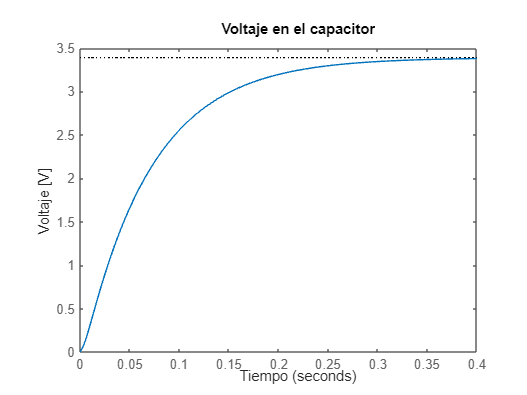

step(4*Transfer_Fuction)
title("Voltaje en el capacitor")
ylabel('Voltaje [V]')
xlabel('Tiempo')

## ESTABILIDAD

clc; syms s

% ESTABILIDAD EXTERNA
disp('Estabilidad externa (T.F)');

Estabilidad externa (T.F)


Polos1 = pole(Transfer_Fuction);
raices = solve(Polos1, s);
disp('Los polos del sistema son:');

Los polos del sistema son:


disp(Polos1);

 -209.6406
  -14.6147



fprintf('\n')

% ESTABILIDAD INTERNA - Método del determinante
disp('Estabilidad interna - Método del determinante');

Estabilidad interna - Método del determinante


Polos2 = det(s*eye(size(A)) - A);
disp(['El polinomio es:', ' ', char(Polos2)]);

El polinomio es: (10540*s)/47 + s^2 + 144000/47


raices = solve(Polos2, s);
disp(['Los polos del sistema son:', ' ', char(raices)]);

Los polos del sistema son: [- (10*210049^(1/2))/47 - 5270/47; (10*210049^(1/2))/47 - 5270/47]


## CONTROLABILIDAD

clc;

% Análisis de Controlabilidad en la entrada
fprintf('CONTROLABILIDAD EN LA ENTRADA')

CONTROLABILIDAD EN LA ENTRADA

Controlabilidad2 = ctrb(A,B)

Controlabilidad2 = 1.0e+03 *

    0.0010   -0.2221
    0.0021    2.1186


Tamano2 = size(Controlabilidad2);
Dimesion2 = rank(Controlabilidad2);
disp('Por el método del comando "ctrb()":');

Por el método del comando "ctrb()":


disp(['El tamaño de la matriz es ','[', num2str(Tamano2),']', ' y el rango es ', num2str(Dimesion2)]);

El tamaño de la matriz es [2  2] y el rango es 2


% Para que el sistema sea completamente controlable la matriz de controlabilidad debe ser de rango completo

## Datos Arduino - Lazo abierto

%Importación de datos reales
data_x = datos_sin_controlar(:, 1);        %Selección la primera columna
DatosReales = data_x(1:80);     % Crea una variable para almacenar los datos

## Gráficas

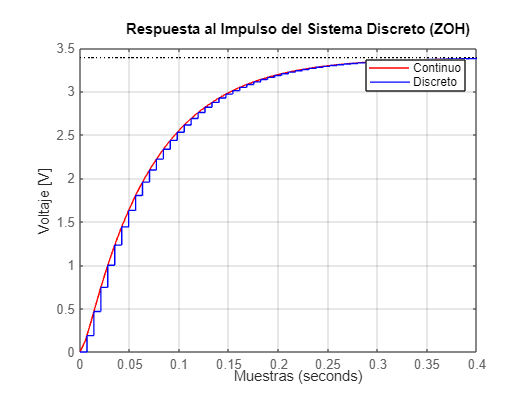

close all;

t2 = linspace(0, 0.4, length(DatosReales));
x0=[0 0];
[y,t1,x1] = lsim(sys, 4*ones(size(t2)),t2,x0);

% Graficar la respuesta al impulso del sistema discreto
figure(1)
plot(t1,y,'r')
hold on
step(4*d_sys,'b');
%plot(t, x(:,2), 'r')
legend('Continuo', 'Discreto')
title('Respuesta al Impulso del Sistema Discreto (ZOH)');
xlabel('Muestras');
ylabel('Voltaje [V]');
grid on

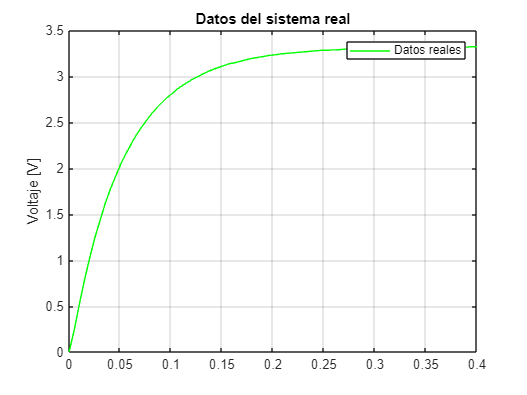


figure(2)
plot(t2, DatosReales, 'g')
legend('Datos reales')
title('Datos del sistema real');
ylabel('Voltaje [V]');
grid on

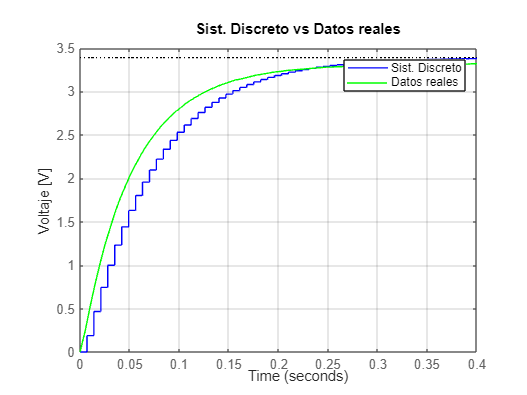


figure(3)
step(4*d_sys,'b');
hold on
plot(t2, DatosReales, 'g')
legend('Sist. Discreto', 'Datos reales')
title('Sist. Discreto vs Datos reales');
ylabel('Voltaje [V]');
grid on

## ASIGNACIÓN DE POLOS

close all; clc;

%Condiciones de diseño
mp = 8;       % sobrenivel
ts = 0.5;      % tiempo de establecimiento
z = sqrt(log(mp)^2)/sqrt(pi^2 + log(mp)^2); % Amortiguamiento
wn = 4/(ts*z);                              % Frecuencia
denominador = [1 2*wn*z wn^2];
p = roots(denominador);

% Discretización de los polos deseados
pd= exp(p.*Ts);

% ASIGNACIÓN DE POLOS
k = acker(Ad,Bd,pd); % Vector de ganacias para la retroalimentación de estado

% Valor de referencia
reff=3;

% Nuevas matrices del sistema en lazo cerrado (controlado)
% f: Feedforward (Retroalimentación)
Af= Ad-(Bd*k)

Af =     0.9054   -0.0005
   16.9412    0.9789


H = inv(Cd*inv(eye(2)-Af)*Bd)  % Precompensación

H = 0.1535

Bf = Bd*H*reff;
sysDiscreto = ss(Af,Bf,CM,D,Ts);

## GRÁFICAS - CONTROL POR RETRO DE ESTADO & PRECOMPENSACIÓN

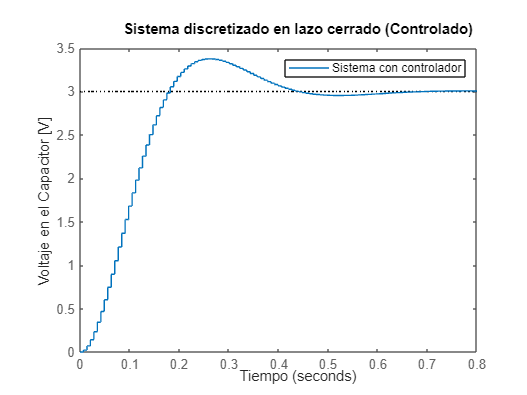

close all; clc;

figure(1)
step(sysDiscreto)
title('Sistema discretizado en lazo cerrado (Controlado)')
ylabel('Voltaje en el Capacitor [V]'); xlabel('Tiempo')
legend('Sistema con controlador')

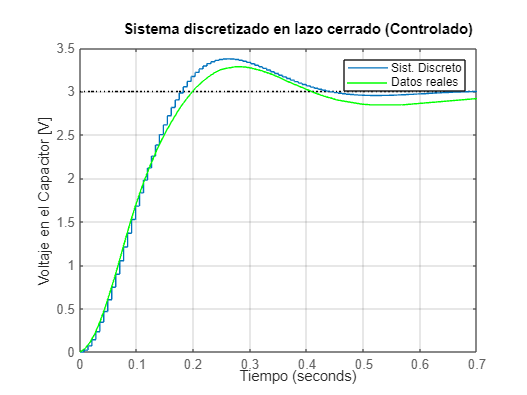



%Importación de datos reales
data_x1 = datosRetro_Precom(:, 1);        %Selección la primera columna
DatosReales2 = data_x1(1:80);     % Crea una variable para almacenar los datos

t3 = linspace(0, 0.7, length(DatosReales2));
x0=[0 0];
[y,t4,x1] = lsim(sys, 3*ones(size(t3)),t3,x0);

figure(2)
step(sysDiscreto)
hold on
plot(t4, DatosReales2, 'g')
grid on
title('Sistema discretizado en lazo cerrado (Controlado)')
ylabel('Voltaje en el Capacitor [V]'); xlabel('Tiempo')
legend('Sist. Discreto', 'Datos reales')
xlim([0 0.7]);

## Esfuerzo de control

Esfuerzo de control: Voltaje y Corriente dados por el DAC

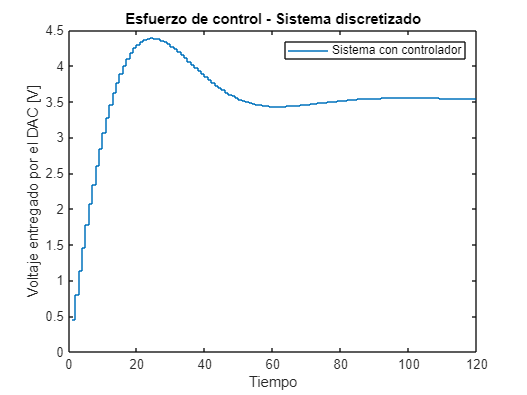

clear up x
close all; clc;

x(:,1)=[0 0]';
for i=1:120
    up(i)=-k*x(:,i)+H*3;
    x(:,i+1)=Ad*x(:,i)+Bd*up(i);
end

figure (1)
stairs(up)
title('Esfuerzo de control - Sistema discretizado')
ylabel('Voltaje entregado por el DAC [V]'); xlabel('Tiempo')
legend('Sistema con controlador')

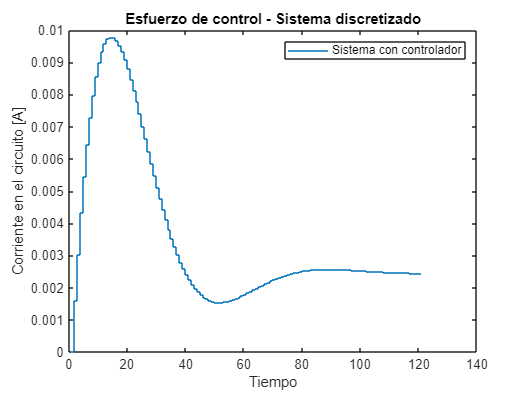

xlimit=[0 120];

figure (2)
stairs(x(1,:))
title('Esfuerzo de control - Sistema discretizado')
ylabel('Corriente en el circuito [A]'); xlabel('Tiempo')
legend('Sistema con controlador')

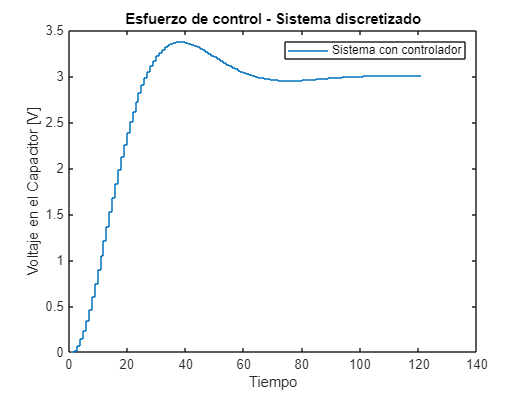


figure (3)
stairs(x(2,:))
title('Esfuerzo de control - Sistema discretizado')
ylabel('Voltaje en el Capacitor [V]'); xlabel('Tiempo')
legend('Sistema con controlador')

## LAZO ABIERTO VS LAZO CERRADO

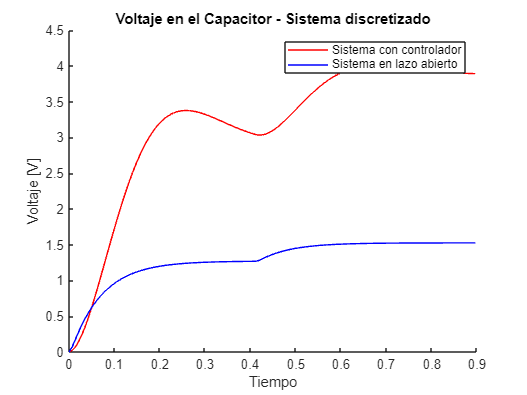

% Vector de tiempo
t = 0:Ts:0.9;
x0=[0 0];

u1=ones(size(t));
%u1(60:80)=1.8;
u1(60:end)=1.3;

u2=1.5*ones(size(t));
%u2(60:80)=1.8;
u2(60:end)=1.8;


[y1, t1] = lsim(sysDiscreto,u1,t,x0);
[y2, t2] = lsim(d_sys, u2,t,x0);

% Gráfico
figure;
hold on;
plot(t1,y1,'r');
plot(t2,y2,'b');
title('Voltaje en el Capacitor - Sistema discretizado');
ylabel('Voltaje [V]'); xlabel('Tiempo')
legend('Sistema con controlador','Sistema en lazo abierto');

## ACCIÓN INTEGRAL

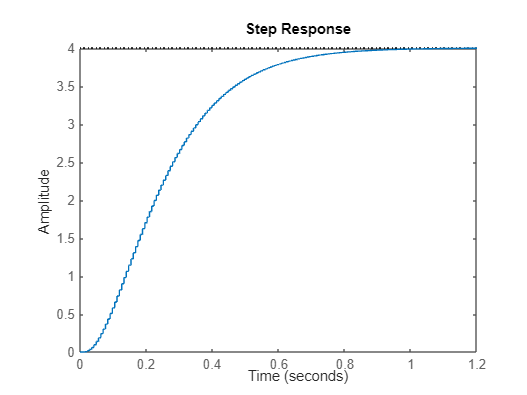

clc; close all;

pNuevo=[p(1),p(2),10*p(1)];
poloDiscreto_AccionInt = exp(real(pNuevo).*Ts);


Af_Intg = [Ad [0;0];-Cd 1];
Bf_Intg = [Bd; 0];

% Vector de ganacias
K2 = acker(Af_Intg,Bf_Intg,poloDiscreto_AccionInt);
K_Retro = K2(1:length(K2)-1); % Ganacia de Retroalimentación
K_Intg = K2(length(K2));      % Ganacia Integral

% Matrices aumentadas discretas en lazo cerrado
Af_Exp = [Af_Intg - Bf_Intg*K2];
Bf_Exp = [zeros(rank(A),1);1];
Cf_Exp = [Cd 0];

% Space State
sysDiscreto_Int = ss(Af_Exp,Bf_Exp,Cf_Exp,D,Ts);
step(4*sysDiscreto_Int)

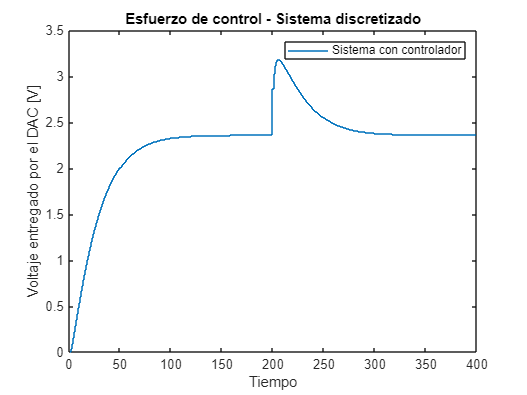

clear x2 up2 error; clc; close all;

% Se debe expandir el vector porque el control integral es un variabe de estado más que se añade al sistema
x2(:,1) = [0 0 0]'; % x2 = [IL Vc Error]
r = 2;
pert=0;

for i = 1:400
    if i >= 200
        pert = 0.5;    % Se crea una perturbacción en un momento arbitrario
    end
    up2(i) = -K2*x2(:,i) + pert;
    x2(:,i+1) = Af_Intg*x2(:,i) + Bf_Intg*up2(i) + [0 0 1]'*r;
end

figure (1)
stairs(up2)
title('Esfuerzo de control - Sistema discretizado')
ylabel('Voltaje entregado por el DAC [V]'); xlabel('Tiempo')
legend('Sistema con controlador')

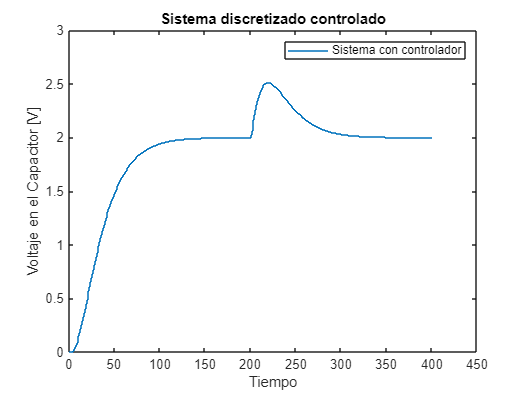


figure (2)
stairs(x2(2,:))
title('Sistema discretizado controlado')
ylabel('Voltaje en el Capacitor [V]'); xlabel('Tiempo')
legend('Sistema con controlador')

## Gráficas - Control Integral

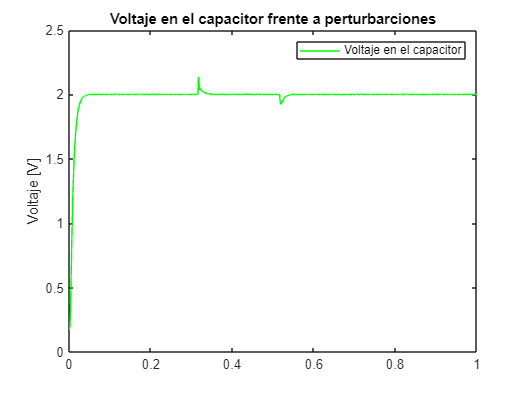

data_Int = datos_control_integral(:, 1);

% Crea una variable para almacenar los datos
DatosReales = data_Int(:);
t2 = linspace(0, 1, 1840);

figure(1)
plot(t2, DatosReales, 'g')
legend('Voltaje en el capacitor')
title('Voltaje en el capacitor frente a perturbarciones');
ylabel('Voltaje [V]');

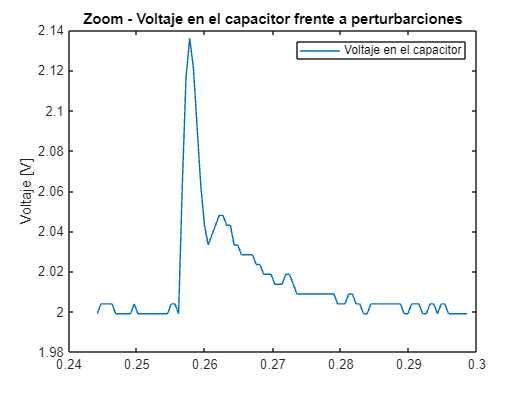


figure(2)
plot(t2(450:550),DatosReales(560:660))
legend('Voltaje en el capacitor')
title('Zoom - Voltaje en el capacitor frente a perturbarciones');
ylabel('Voltaje [V]');

## Función: Solucionar E.D.O's con ode45

% Define the system function
function dxdt = system(t, x)
R1=1000;    % [Ohm]
R2=220;     % [Ohm]
R3=1000;    % [Ohm]
L=1000e-6;  % [mHenrrios]
C=470e-6;   % [Faradios]
Vi=4;       % [Voltios]
dxdt = [x(1)*(-R2/L) - x(2)/L + Vi/L; x(1)/C - x(2)*((R1+R3)/(R1*R3*C)) + Vi/(R1*C)];
end